clear;
datasetName = "dataset8";
files = metadata.selectPreset(metadata.collect('DataSet'), datasetName);
[X, Y, featureTbl, featureNames] = features.pipeline(files);
sigTable = preprocess.buildSignalTable(files, 1, 0, @io.readCurrent, @io.readVibro);

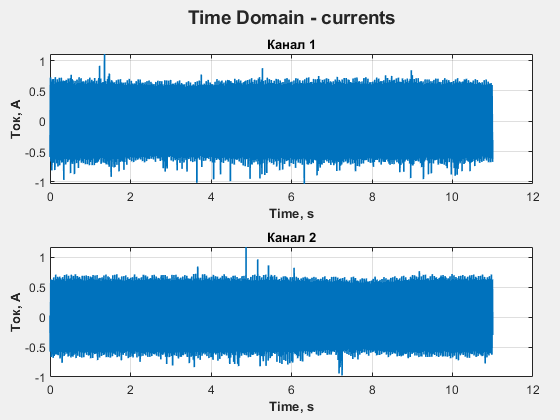

% SIGNALS
file = files.FilePath(7);
subSigTable = preprocess.findRowsByFilePath(sigTable, file);

opts.signalType = 'currents';
fig1 = viz.windowTimeDomain(subSigTable, opts);
fig2 = viz.windowFreqDomain(subSigTable, opts);
set(fig1, 'Visible', 'on');

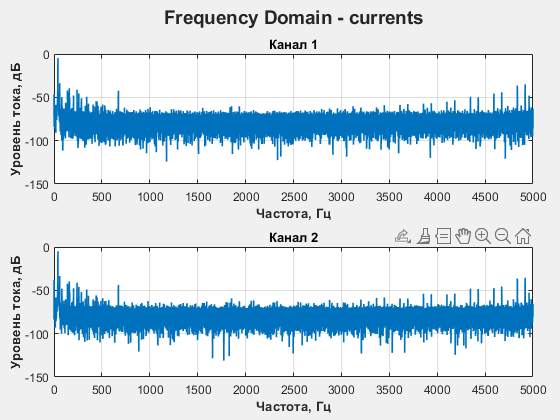

set(fig2, 'Visible', 'on');

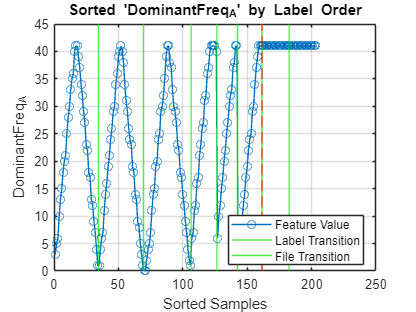

% FEATURES
% === SETUP ===
featureToInspect = "DominantFreq_A";
labelOrder = ["healthy", "system misalignment", "misalignment", "faulty bearing"];

% === FILTER AND PREPARE DATA ===
% Extract feature and label vectors
featureVector = featureTbl.(featureToInspect);
labelVector = string(featureTbl.label);
fileVector   = string(featureTbl.metaCurrent.FilePath); % Get file paths

% Keep only valid labels defined in labelOrder
isValid = ismember(labelVector, labelOrder);
featureVector = featureVector(isValid);
labelVector   = labelVector(isValid);
fileVector    = fileVector(isValid);

% Map labels to numeric using labelOrder
labelNumeric = zeros(length(labelVector), 1);
for i = 1:length(labelOrder)
    labelNumeric(labelVector == labelOrder(i)) = i;
end

% === SORT BASED ON labelOrder ===
[~, sortIdx] = sort(labelNumeric);
sortedFeature = featureVector(sortIdx);
sortedLabel   = labelVector(sortIdx);
sortedFiles   = fileVector(sortIdx);

% === PLOTTING ===
figure;
plot(sortedFeature, '-o')
title("Sorted '" + featureToInspect + "' by Label Order")
xlabel('Sorted Samples')
ylabel(featureToInspect)
grid on
hold on

% === ADD VERTICAL LINES: FILE TRANSITIONS ===
% Detect where the FilePath changes
fileChangeIdx = find(~strcmp(sortedFiles(1:end-1), sortedFiles(2:end)));
for i = 1:length(fileChangeIdx)
    xline(fileChangeIdx(i) + 0.5, 'Color', [0 0.9 0], 'LineStyle', '-', 'LineWidth', 1.0, ...
        'DisplayName', 'File Transition');
end

% === ADD VERTICAL LINES: LABEL TRANSITIONS ===
% Find transitions in sorted labels
labelChangeIdx = find(diff(labelNumeric(sortIdx)) ~= 0);
for k = 1:length(labelChangeIdx)
    xline(labelChangeIdx(k)+0.5, 'r--', 'LineWidth', 1.2, ...
        'DisplayName', "Label: " + sortedLabel(labelChangeIdx(k)));
end

% === LEGEND / LABELS ===
% We'll avoid cluttering legend with duplicates
[~, uniqueIdx] = unique(sortedLabel(labelChangeIdx), 'stable');
legendEntries = sortedLabel(labelChangeIdx(uniqueIdx));
legend(["Feature Value", "Label Transition", "File Transition"], 'Location', 'best');

hold off;